# Eksempel 1

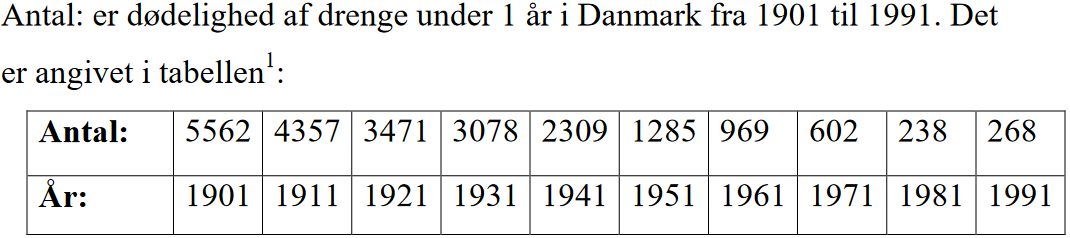

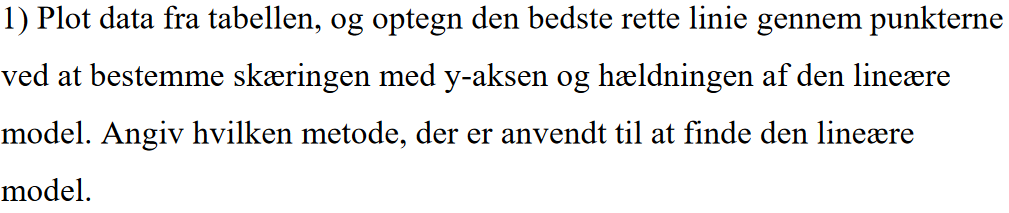

clearvars
format bank
close all
antal = [5562, 4357, 3471, 3078, 2309, 1285, 969, 602, 238, 268];
year = 1901:10:1991;
coeffs = polyfit(year, antal, 1)

coeffs =         -59.50     118000.90


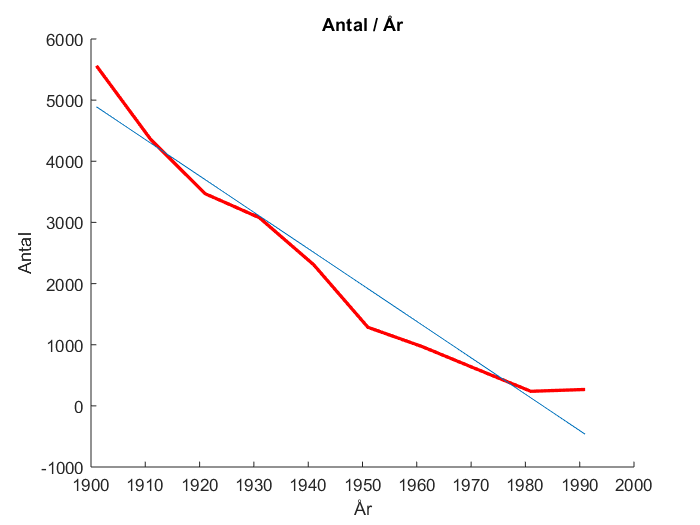

y = coeffs(1)*year+coeffs(2);
figure(1)
hold on
xlabel("År"); ylabel("Antal"); title("Antal / År");
plot(year,antal,'-r','LineWidth',2)
plot(year, y)


% Linær funktion = a*x+b
% a = hældning, b = skæring med y
alpha = coeffs(1)

alpha =         -59.50


beta = coeffs(2)

beta =      118000.90


res = antal - (alpha*year+beta)

res =         670.60         60.60       -230.40        -28.40       -202.40       -631.40       -352.40       -124.40        106.60        731.60


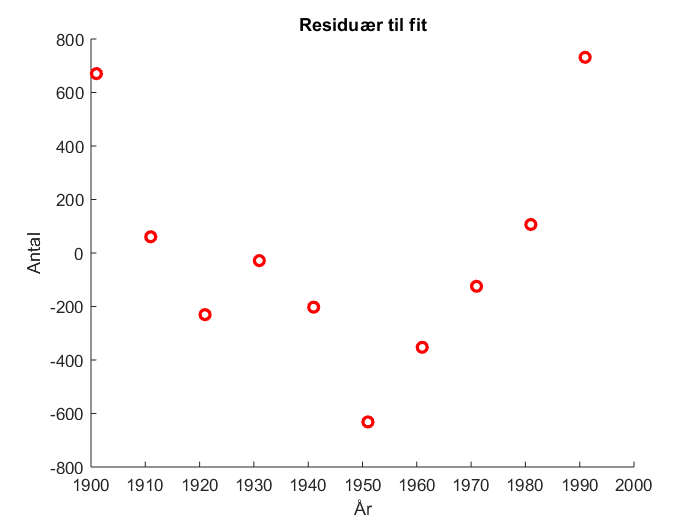

figure(2)
hold on
xlabel("År"); ylabel("Antal"); title("Residuær til fit");
scatter(year, res,'or','LineWidt', 2)

n = length(year); % Sample Size
sr2 = (1/(n-2)) * sum( res.^2 )

sr2 =      204145.30


t0 = tinv(0.975, n-2);
yearsMean = mean(year)

yearsMean =        1946.00


ConfMinus = alpha - t0 *sqrt(sr2/sum((year - yearsMean).^2))

ConfMinus =         -70.97


ConfPlus = alpha + t0 *sqrt(sr2/sum((year - yearsMean).^2))

ConfPlus =         -48.03


Sample size er lille. Residualerne er systematisk under 0. Der forventes stor afviglse efter 1991, da dødstal ikke kan være negative

# Eksempel 2

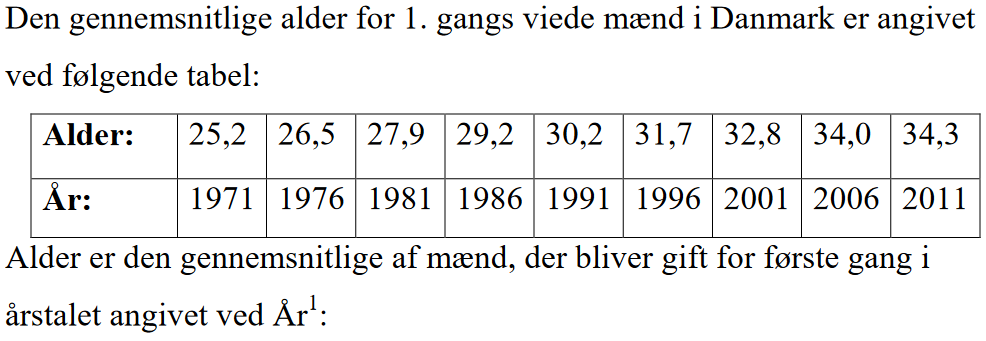

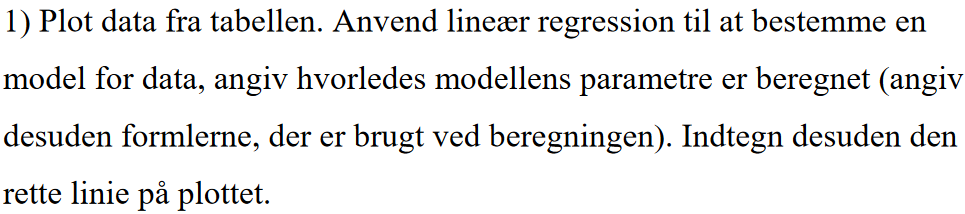

clearvars
close all
alder = [25.2, 26.5, 27.9, 29.2, 30.2, 31.7, 32.8, 34.0, 34.3];
years = 1971:5:2011;
figure(1)
hold on
xlabel("År"); ylabel("Alder"); title("Alder / År");
plot(years, alder, '-r', 'LineWidth',2)
coeffs = polyfit(years, alder, 1);
alpha = coeffs(1)

alpha =           0.24


beta = coeffs(2)

beta =        -442.33


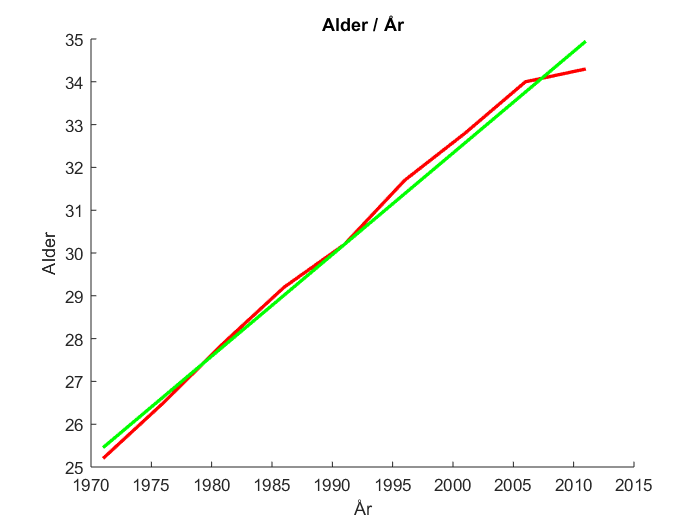

fit = alpha*years+beta;
plot(years, fit, '-g','LineWidth',2)

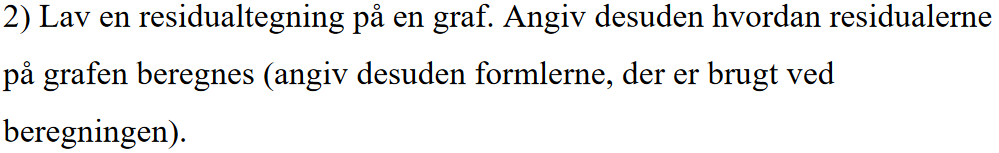

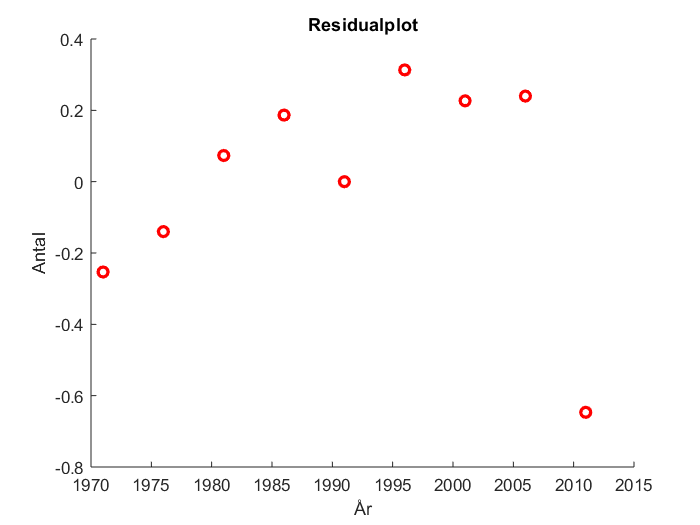

res = alder - (alpha*years+beta);
figure(2)
hold on
xlabel("År"); ylabel("Antal"); title("Residualplot");
scatter(years,res,'or', 'LineWidth',2)